# Natural Vibration of Euler-Bernoulli Beam

    6.0529



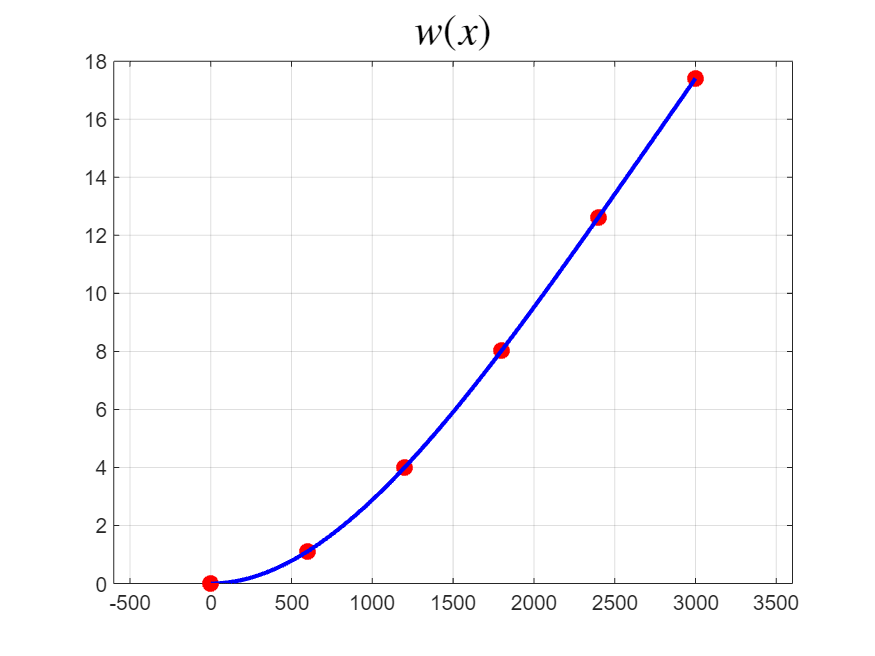

clear; clc; close all

[Delg, x, w, dwdx, d2wdx2] = FEA(5, 1);

function [Delg, x, w, dwdx, d2wdx2] = FEA(N, ModeNumber)

    % force in N, length in mm and time in s
    Ae = 50^2-44^2;
    Ie = 50^4/12 - 44^4/12;
    Ee = 200000;
    rhoe = 7.8e-9;
    EIe = Ee*Ie;
    L = 3000;
    p=2;

    he=L/N; %Geometric parameter
    
    TotalDoFs = 2*N*(p-1)+2; %TotalNodes and TotalDoFs
    


    Essential_BC_DoFs = [1, 2];
    Essential_BCs = [0, 0];
    r = length(Essential_BC_DoFs);
    Delg = zeros(TotalDoFs, 1);
    for i=1:r
        DoF = Essential_BC_DoFs(i);
        Delg(DoF) = Essential_BCs(i);
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%%%% ASSEMBLY %%%%%%   
    Kg = zeros(TotalDoFs);
    Mg = zeros(TotalDoFs);

    for e=1:N
        
        [Ke, Me] = EM(EIe, Ae, Ie, rhoe, he);

        for i=1:2*p
            I = 2*(e-1)*(p-1)+i;
            for j=1:2*p
                J = 2*(e-1)*(p-1)+j;
                Kg(I, J) = Kg(I, J) +  Ke(i, j);
                Mg(I, J) = Mg(I, J) +  Me(i, j);
            end
        end
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%%%% CONDENSATION %%%%%
    Kc = Kg; Mc = Mg; DelcRows = 1:TotalDoFs;
    Kc(Essential_BC_DoFs, :) = [];
    Kc(:, Essential_BC_DoFs) = [];
    Mc(Essential_BC_DoFs, :) = [];
    Mc(:, Essential_BC_DoFs) = [];
    DelcRows(Essential_BC_DoFs) = [];
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%%%%% Finding the eigenvalues %%%%%%
    [eigenvectors, eigenvalues] = eig(Kc,Mc);
    [sorted_eigenvalues, sorted_indices] = sort(diag(eigenvalues));
    sorted_eigenvectors = eigenvectors(:, sorted_indices);

    Omega = sqrt(real(sorted_eigenvalues(ModeNumber)));
    NatFreq = Omega/(2*pi);
    disp(NatFreq);

    EigenMode = sorted_eigenvectors(:, ModeNumber);

    for i=1:(TotalDoFs-r)
        Delg(DelcRows(i)) = EigenMode(i);
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%% VISUALIZATION %%%%%%
    ptsEL=50;
    [x, w, dwdx, d2wdx2] = wSol(Delg, N, he, ptsEL);

% subplot(3, 1, 1);
figure;
    xVec = linspace(0, L, TotalDoFs/2);
    plot(xVec, Delg(1:2:TotalDoFs), ".", MarkerSize=24, Color="red")
    xlim([0-he, L+he]);
    title("$w(x)$", Interpreter="latex", FontSize=20);
    hold on; grid on;
    plot(x, w, LineWidth=2, Color="blue");
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    

 end

#### Function to evaluate element matrices

function [Ke, Me] = EM(EIe, Ae, Ie, rhoe, he)
    Ke = 2*(EIe/he^3)*[6 -3*he -6 -3*he; 
                       -3*he 2*he^2 3*he he^2;
                       -6 3*he 6 3*he
                       -3*he he^2 3*he 2*he^2];

    T1 = [156, -22*he, 54, 13*he;
          -22*he, 4*he^2, -13*he, -3*he^2;
          54, -13*he, 156, 22*he;
          13*he, -3*he^2, 22*he, 4*he^2];

    T2 = [36, -3*he, -36, -3*he;
         -3*he, 4*he^2, 3*he, -he^2;
         -36, 3*he, 36, 3*he;
         -3*he, -he^2, 3*he, 4*he^2];
    
    Me = rhoe*Ae*he/420*T1 + rhoe*Ie/(30*he)*T2;
   
end


#### Functions for post-processing

function out = wex(x, xej, Delej)
    p = length(xej);
    he = xej(p) - xej(1);
    xbar = (x-xej(1))/he;

    phi0 = 1-3*xbar.^2+2*xbar.^3;
    phi1 = -he*xbar.*(1-xbar).^2;
    phi2 = 3*xbar.^2-2*xbar.^3;
    phi3 = -he*xbar.*(xbar.^2-xbar);

    phiVec=[phi0,phi1,phi2,phi3];

    out = zeros(length(xbar), 1);
    for i=1:length(xbar)
        out(i) =phiVec(i, :)*Delej;
    end
    
end

function out = dwedx(x, xej, Delej)
    p = length(xej);
    he = xej(p) - xej(1);
    xbar = (x-xej(1))/he;

    dphi0dx = -6*xbar/he+6*xbar.^2/he;
    dphi1dx = -(1-xbar).^2 + xbar.*2.*(1-xbar);
    dphi2dx = 6*xbar/he-6*xbar.^2/he;
    dphi3dx = -(xbar.^2-xbar) -xbar.*(2.*xbar-1);

    dphidxVec=[dphi0dx,dphi1dx,dphi2dx,dphi3dx];  

    out = zeros(length(xbar), 1);
    for i=1:length(xbar)
        out(i) =dphidxVec(i, :)*Delej;
    end
end

function out = d2wedx2(x, xej, Delej)
    p = length(xej);
    he = xej(p) - xej(1);
    xbar = (x-xej(1))/he;

    d2phi0dx2 = -6/he.^2+12*xbar/he.^2;
    d2phi1dx2 = 2*(1-xbar)/he + 2/he - 4*xbar/he;
    d2phi2dx2 = 6/he.^2-12*xbar/he.^2;
    d2phi3dx2 = -(2*xbar/he-1/he) -4*xbar/he + 1/he;

    d2phidx2Vec=[d2phi0dx2,d2phi1dx2,d2phi2dx2,d2phi3dx2]; 

    out = zeros(length(xbar), 1);
    for i=1:length(xbar)
        out(i) = d2phidx2Vec(i, :)*Delej;
    end
end


function [Mat1, Mat2, Mat3, Mat4] = wSol(Delg, N, he, ptsEL)
    p=2;
    Mat1 = double.empty;
    Mat2 = Mat1;
    Mat3 = Mat1;
    Mat4 = Mat1;
    
    for e=1:N
        xej = linspace(he*(e-1), he*e, 2);
        Delej = Delg((e-1)*(p-1)*2+1:((e)*(p-1)*2+2));

        x = linspace(xej(1), xej(2), ptsEL)';
        
        w = wex(x, xej, Delej);
        dwdx = dwedx(x,xej,Delej);
        d2wdx2 = d2wedx2(x,xej,Delej);

        Mat1 = [Mat1, x];
        Mat2 = [Mat2, w];
        Mat3 = [Mat3, dwdx];
        Mat4 = [Mat4, d2wdx2];
    end
end
